## **Extract Data From Arrythmia Database**

% set up environment and add path to the databse
currentPath = pwd;
clear;
clc;
pathToSamples = 'C:\Users\hsuen\Desktop\Interpretable Machine Learning\Data\mit-bih-arrhythmia-database-1.0.0\mit-bih-arrhythmia-database-1.0.0';
% first extract the location of QRS waves from the annotation files
% provided from the database


listing = dir(strcat(pathToSamples,'\*.atr')); % find files that have annotations associated with them
numSamples = length(listing);

arrythmiaSamples = cell(numSamples,1);


% build up a vector that contains the file names
for i = 1:numSamples
   [~,name,~] = fileparts(listing(i).name);
   arrythmiaSamples{i} = name;
end



annotator = 'atr'; % char array specifing the file extension for the annotations
metaDataArrythmia = cell(numSamples,5); % cell array to hold all of the data

% move to where the samples in order to read their data
cd(pathToSamples)

for i = 1:numSamples
    
    % read annotations for each sample
    currentSample= arrythmiaSamples{i};
    [currentAnn, currentAnnType] = rdann(currentSample, annotator); % WFDB function to read annotations
    
    % read signal data for each sample
    wfdb2mat(currentSample);
    [tm,signal,Fs,labels]=rdmat(strcat(currentSample, 'm'));
    metaDataArrythmia{i, 1} = tm(currentAnn);
    metaDataArrythmia{i, 2} = currentAnn;
    metaDataArrythmia{i, 3} = signal(:,1);
    metaDataArrythmia{i, 4} = signal(:,2); % fourth column for signal channels
    metaDataArrythmia{i, 5} = 1 ;% flag to note that this is abnormal heart rythym. 
end

## **Extract Data From Normal Sinus Rythm Database**

% since the samples for normal heartbeats are not sequential as was the
% case for arrythmia, need to extract the names of the samples
pathToNormalSamples = 'C:\Users\hsuen\Desktop\Interpretable Machine Learning\Data\mit-bih-normal-sinus-rhythm-database-1.0.0\mit-bih-normal-sinus-rhythm-database-1.0.0';
listing = dir(strcat(pathToNormalSamples,'\*.atr')); % find files that have annotations associated with them
numSamples = length(listing);

normalSamples = cell(numSamples,1);


% build up a vector that contains the file names
for i = 1:numSamples
   [~,name,~] = fileparts(listing(i).name);
   normalSamples{i} = name;
end

% move into the directory where the normal samples are located
cd(pathToNormalSamples);

metaDataNormal = cell(numSamples,5);

for i = 1:numSamples
    % read annotations for each sample
    currentSample= normalSamples{i};
    [currentAnn, currentAnntype] = rdann(currentSample, annotator); % WFDB function to read annotations
    
    
    % read signal data for each sample
    wfdb2mat(currentSample);
    [tm,signal,Fs,labels]=rdmat(strcat(currentSample, 'm'));
    metaDataNormal{i,1} = tm(currentAnn);
    metaDataNormal{i,2} = currentAnn;
    metaDataNormal{i,3} = signal(:,1);
    metaDataNormal{i,4} = signal(:,2); % fourth column for signal channels
    metaDataNormal{i,5} = 0; % flag to note that this is normal heart rythym. 
end

## **Feature Extraction From Annotations**

We will extract the following 6 features from the data:

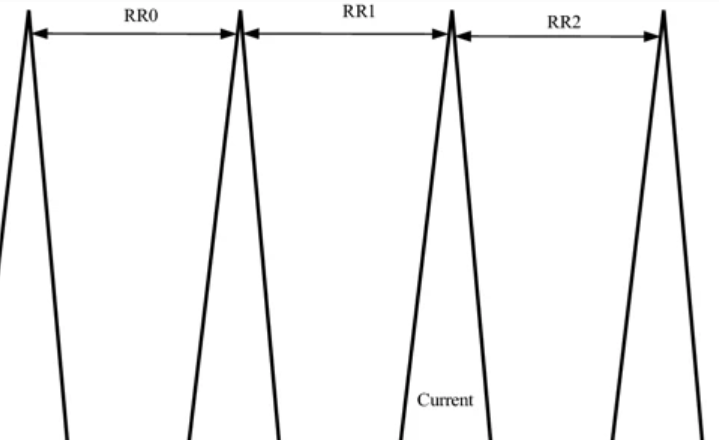

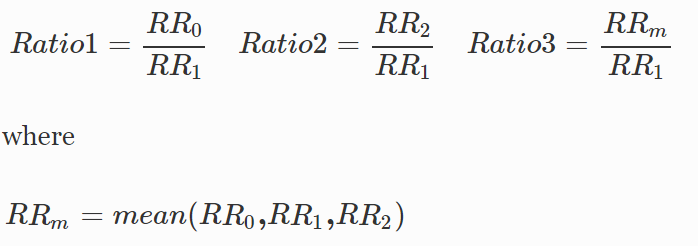

In addition to these 6 features, we will extract the amplitude of the R wave at each heartbeat. There will be two readings for the amplitude, one for each channel, which gives us a total of 8 features to use for learning.

% first combine all the data together
metaData = [metaDataArrythmia ; metaDataNormal];

% to speed up processing, specify the number of "observations" to get out
% of each patient. INCREASE for better performance 
numObservationsPerPatient = 1000;
numPatients = size(metaData,1); % get the total number of samples
trainData = cell(numObservationsPerPatient * numPatients, 9); % intialize design matrix for machine learning

counter = 1;
% divide each patient into several observations and extract features
for i = 1:numPatients
    rPeaks = metaData{i,1};
    annotations = metaData{i,2};
    sig1 = metaData{i,3};
    sig2 = metaData{i,4};
    labelHeart = metaData{i,5};
    for j = 3:numObservationsPerPatient + 3
        % extract all features for this observations
        RR0 = rPeaks(j-1) - rPeaks(j-2);
        RR1 = rPeaks(j) - rPeaks(j-1);
        RR2 = rPeaks(j+1) - rPeaks(j);
        R1 = RR0/RR1;
        R2 = RR2/RR1;
        Rm = mean([RR0, RR1,RR2])/ RR1;
        rAmplitude1 = sig1(annotations(j));
        rAmplitude2 = sig2(annotations(j));
        
        % input features into design matrix
        trainData{counter, 1} = RR0;
        trainData{counter, 2} = RR1;
        trainData{counter, 3} = RR2;
        trainData{counter, 4} = R1;
        trainData{counter,5} = R2;
        trainData{counter,6} = Rm;
        trainData{counter, 7} = rAmplitude1;
        trainData{counter, 8} = rAmplitude2;
        trainData{counter, 9} = labelHeart;
        counter = counter + 1;
    end
end

## **Partition Data Into Training and Testing**

percentTrain = 0.8;
[observations, features] = size(trainData);
idx = randperm(observations);
numTrain = round(0.7*observations);
numTest = observations - numTrain;

testData = trainData(idx(1:numTest),:);
trainData = trainData(idx(numTest+1:end),:);

variableNames = {'RR0', 'RR1', 'RR2', 'R1', 'R2', 'Rm', 'rAmplitude1', 'rAmplitude2', 'abnormal'};

% format data for functions
testData = cell2table(testData, 'VariableNames',variableNames);
trainData = cell2table(trainData, 'VariableNames',variableNames);

## **Save Data For Future Sessions**

save('data', 'trainData', 'testData');
save('variableNames', 'variableNames');

## **Train Models**

% if already have the .MAT files can start the demo here
clear;
clc;
addpath('MATFiles\');
load data
load variableNames
% LAUNCH CLASSIFICATION LEARNER TO TRAIN A SEVERAL MODEL QUICKLY AND EASILY

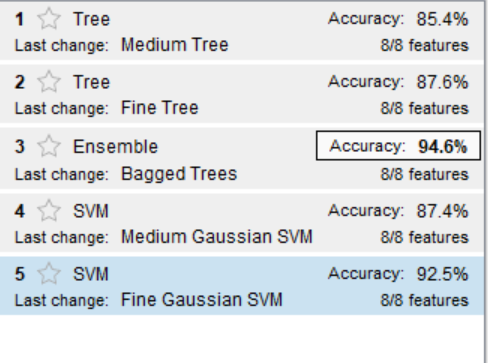

We see instantly that more complicated modles, such as a bagged ensemble and an SVM perform better, at the cost of being less "interpretable" models. Decision trees have worse performance, however, the mechanics of how they work is much more clear, as will be demonstrated later.

% alternatively load trained models from folder
addpath('MATFiles\trainedModels\')
load mediumTree
load fineGaussian
load baggedTree

MATLAB can train models programmatically as well, allowing the user to customize several hyperparameters

Find all available options to tweak here: 

[https://www.mathworks.com/help/stats/fitctree.html#namevaluepairarguments](https://www.mathworks.com/help/stats/fitctree.html#namevaluepairarguments)

[https://www.mathworks.com/help/stats/fitcensemble.html#namevaluepairs](https://www.mathworks.com/help/stats/fitcensemble.html#namevaluepairs)

[https://www.mathworks.com/help/stats/fitcsvm.html](https://www.mathworks.com/help/stats/fitcsvm.html)

mediumTree = fitctree(trainData,"abnormal", 'MaxNumSplits', 30, 'MinParentSize',15, ...
    "SplitCriterion","gdi");

baggedTree = fitcensemble(trainData,"abnormal", 'Method','Bag',...
    'Learners','tree', 'NumLearningCycles',100);

fineGaussian = fitcsvm(trainData, "abnormal", "KernelFunction","gaussian", ...
    'KernelScale',sqrt(height(trainData)/4), 'BoxConstraint',2);


## **Measure Generalization Accuracy For Individual Models**

response = testData.abnormal;
% accuracy of decision tree
preds = mediumTree.predictFcn(testData(:,1:end-1));
accTree = sum(preds == response)/numel(response)

accTree = 0.8538

% accuracy of bagged tree
preds = baggedTree.predictFcn(testData(:,1:end-1));
accBaggedTree = sum(preds == response)/numel(response)

accBaggedTree = 0.9486



% accuracy of decision tree
preds = fineGaussian.predictFcn(testData(:,1:end-1));
accSVM = sum(preds == response)/numel(response)

accSVM = 0.9259

## **Examine Interpretablity **

### **Decision Tree**

Our decision tree performed the worst; however, it has the added benefit of being the most interpretable. MATLAB makes it easy to view the mechanics of our model

% text description of our trained tree:
view(mediumTree.ClassificationTree)


Decision tree for classification
 1  if rAmplitude1<0.6275 then node 2 elseif rAmplitude1>=0.6275 then node 3 else 1
 2  if RR0<0.680122 then node 4 elseif RR0>=0.680122 then node 5 else 1
 3  if RR1<0.836024 then node 6 elseif RR1>=0.836024 then node 7 else 1
 4  if rAmplitude1<-0.75 then node 8 elseif rAmplitude1>=-0.75 then node 9 else 0
 5  if rAmplitude2<-0.2275 then node 10 elseif rAmplitude2>=-0.2275 then node 11 else 1
 6  if rAmplitude2<-0.5575 then node 12 elseif rAmplitude2>=-0.5575 then node 13 else 1
 7  if rAmplitude2<0.4925 then node 14 elseif rAmplitude2>=0.4925 then node 15 else 1
 8  class = 1
 9  if RR1<0.711024 then node 16 elseif RR1>=0.711024 then node 17 else 0
10  if rAmplitude2<-1.0625 then node 18 elseif rAmplitude2>=-1.0625 then node 19 else 1
11  if rAmplitude1<-0.1675 then node 20 elseif rAmplitude1>=-0.1675 then node 21 else 1
12  class = 1
13  if rAmplitude1<2.0525 then node 22 elseif rAmplitude1>=2.0525 then node 23 else 1
14  class = 1
15  if rAmplitud

The textual description of this can be quite hard to understand. Let's try a more visual approach:

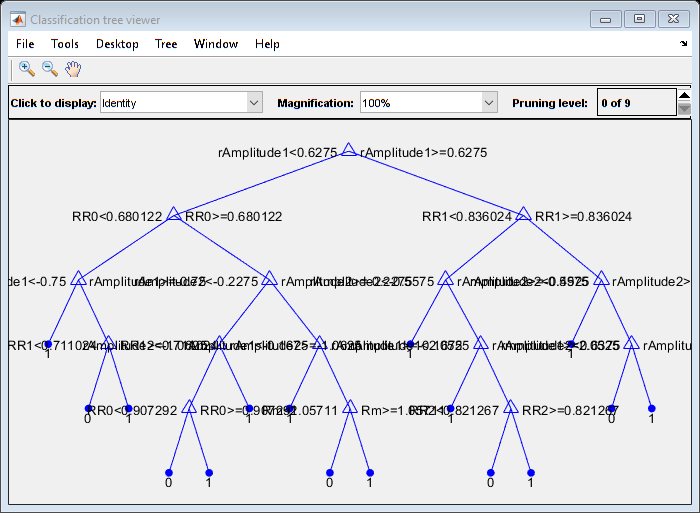

view(mediumTree.ClassificationTree,'mode','graph')

The pop up graphical user interface allows you to specify what characteristics of the tree you would like to see, zoom in, and inspect the decision boundaries for each node. MATLAB makes it intuitive and easy to visualize the mechanics of how a classification tree works for a particular problem

We immediately see that the first thing the decision tree looks at is the amplitude of the R wave. From there, depending on the amplitude, the tree looks at either the RR1 interval or the RR0 interval to further descend down the tree. 

### **Bagged Tree**

The bagged tree performs much better than our single decision tree, but it would be a lot harder to visualize each of the individual trees to get a sense of how the model works. What we can do instead is examine how important individual features are to the model, by permuting through different possible values for each predictor and examining how much the response of the model changes

Imp = oobPermutedPredictorImportance(baggedTree.ClassificationEnsemble);
[sortedImp, idx] = sort(Imp, 'descend');
rankedPredictors = variableNames(idx)

rankedPredictors = 1×8 cell array
    {'rAmplitude1'}    {'rAmplitude2'}    {'Rm'}    {'RR2'}    {'R1'}    {'R2'}    {'RR0'}    {'RR1'}


It becomes clear from the permuted predictor importance method that the two amplitude signals have the largest effect on the outcome, followed by the ratio Rm, and the interval RR2. (please go here to see an explanation of what each predictor variable corresponds to)

Note we can perform a similar method of examining predictor importance for just our decision tree. This works in a slightly different way by summing changes in node impurity across each split.

impSingleTree = predictorImportance(mediumTree.ClassificationTree);
[sortedImpSingleTree, idxSingleTree] = sort(impSingleTree, 'descend');
rankedPredictorsSingleTree = variableNames(idxSingleTree)

rankedPredictorsSingleTree = 1×8 cell array
    {'rAmplitude1'}    {'RR0'}    {'rAmplitude2'}    {'RR1'}    {'Rm'}    {'RR2'}    {'R1'}    {'R2'}


Note that even for the single decision tree, the "R" amplitudes contribute heavily to the prediction. However, the single decision tree includes the interval RR0 as one of the top four predictors, which the bagged ensemble does not.This shows us that the single decision tree puts more emphasis on ther predictors, and accounts for some of the discrepancy in their performances.

## **PDP/ICE for Classification**

Our SVM also performs with very respectable amount of accuracy. For high performing models outside of Bagged Trees, we can visualize the effect of a feature on the output using partial dependece plots to help us interpret the model. Let us see if the amplitude of the R wave, which we foud was significant in the bagged tree, to be significant for our SVM as well 

variableNames % visualize variable names to see what variables we want to evaluate

variableNames = 1×9 cell array
    {'RR0'}    {'RR1'}    {'RR2'}    {'R1'}    {'R2'}    {'Rm'}    {'rAmplitude1'}    {'rAmplitude2'}    {'abnormal'}


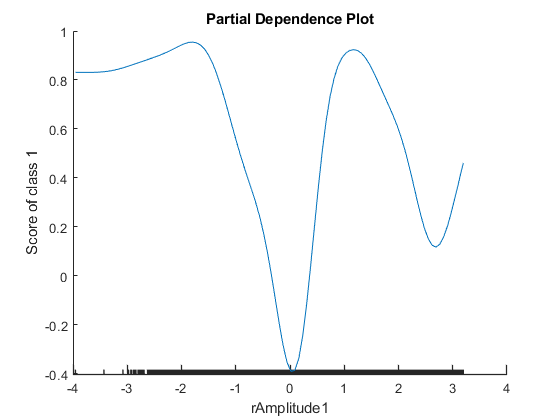

plotPartialDependence(fineGaussian.ClassificationSVM, 7, 2);

We can see that when the rAmplitude is around 0, then the prediction score for being "abnormal" (class 1) is close to zero, whereas values of rAmplitude that are nevative or in the range of 0 to 1.2 lead to higher scores. This implies that the rAmplitude is also an important predictor for our SVM. On top of that, it tells us HOW exactly the rAmplitude affects our response, namely by showing us which values of rAmplitude lead to what sorts of prediction scores. 

## **LIME**

Instead of looking at predictors as a whole, across an entire data set, we can examine individual predictions and see what factors are most important for a specific prediction

The steps go this way:

1) generate syn data from actual data

2) compute distances for all syn data points from the query point

3) convert these distances to weights

4) select important features from this weighted syn data (statistical measure, internal function)

5) fit a simple model just for these features using the weighted syn data

Steps are the same for global versus local (for global, we just generate a whole bunch of data points first so we don't have to re-create syn data points for each new query point). 

    
% create lime object
limeobj = lime(fineGaussian.ClassificationSVM, 'Type','classification');

% use lime object to get explanations for the first observation in our test
% class. Look at the first three important predictors
limeobj = fit(limeobj,testData(1,1:end-1),3);

% visualize our first observation:
testData(1,:)

ans = 1×9 table
     RR0       RR1       RR2       R1        R2        Rm      rAmplitude1    rAmplitude2    abnormal
    ______    ______    _____    ______    ______    ______    ___________    ___________    ________

    1.2194    1.1889    1.375    1.0257    1.1565    1.0607       1.055          0.33           1    


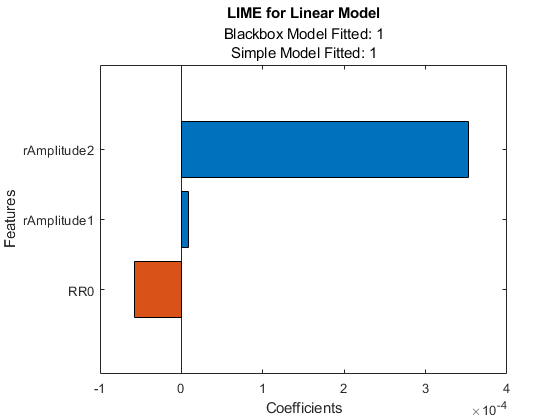


% Plot the explanations. This plot consists of the important features recognized by lime locally around the point
f = plot(limeobj);

As you can see that for the very first observation in our data set, the top three variables were the RR0 interval, as well as the amplitude from the two channels 

## **Visualizing Our Results**

We can create graphs for us to see all these results and plot our results in a more customizable format

Lets open up our custom app-designer tool we have made for this ECG example to showcase our results in a more intuitive way 